Monaco_Quali = readtable('Laptime CSV Data/2023 Season/MonacoGP/2023 Monaco Quali.csv');

Sector_1 = table2array(Monaco_Quali(:,9));
Sector_2 = table2array(Monaco_Quali(:,11));
Sector_3 = table2array(Monaco_Quali(:,13));

sectorNumbers = [1 2 3];
sectorTimes = [Sector_1 Sector_2 Sector_3];

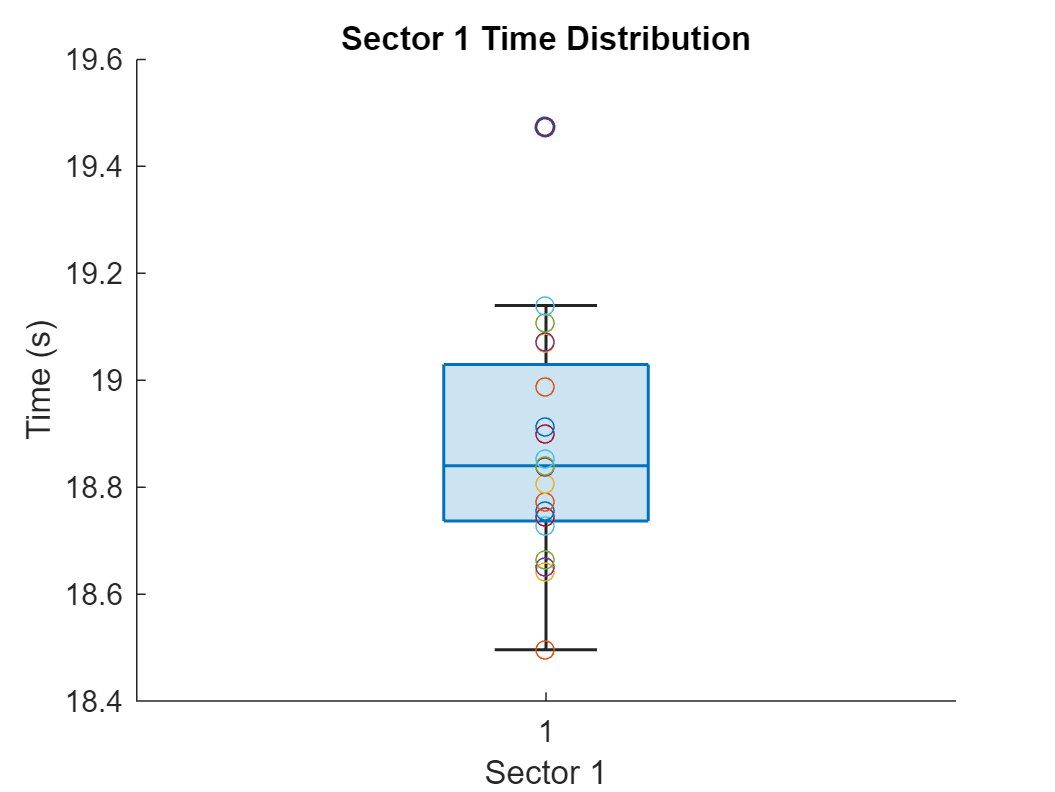

boxchart(sectorTimes(:,1));
hold on
scatter(1, sectorTimes(:,1))
ylabel('Time (s)');
xlabel('Sector 1');
title('Sector 1 Time Distribution');
hold off

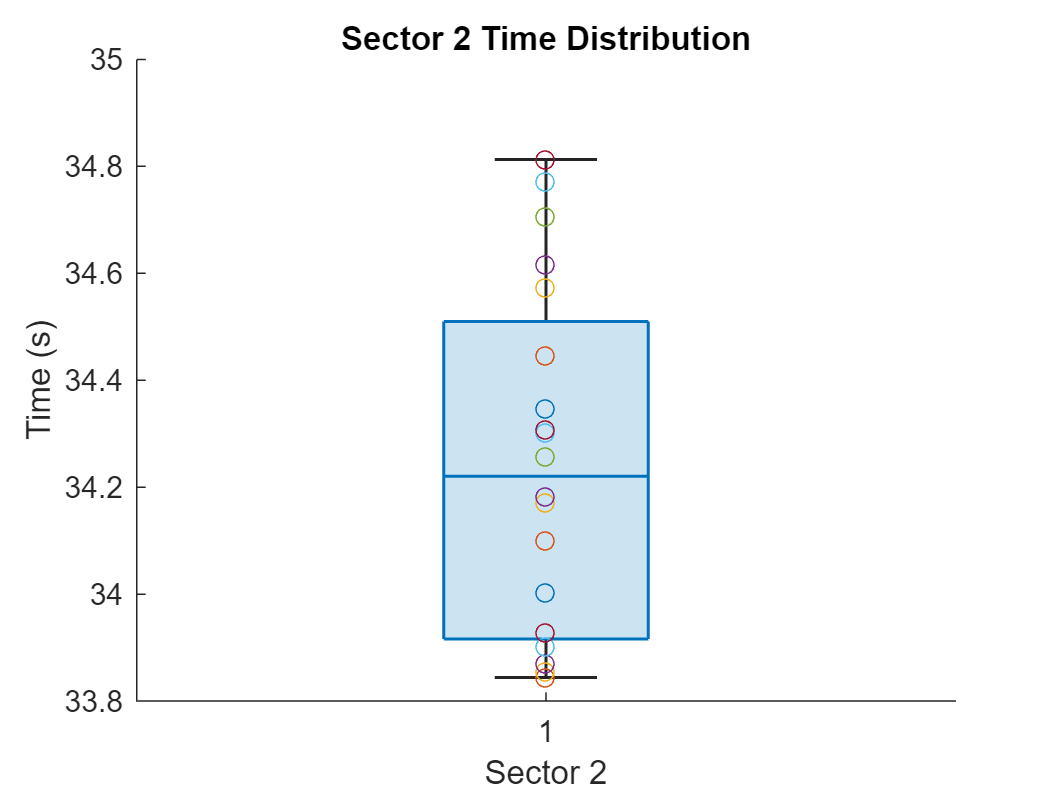


boxchart(sectorTimes(:,2));
hold on
scatter(1, sectorTimes(:,2))
ylabel('Time (s)');
xlabel('Sector 2');
title('Sector 2 Time Distribution');
hold off

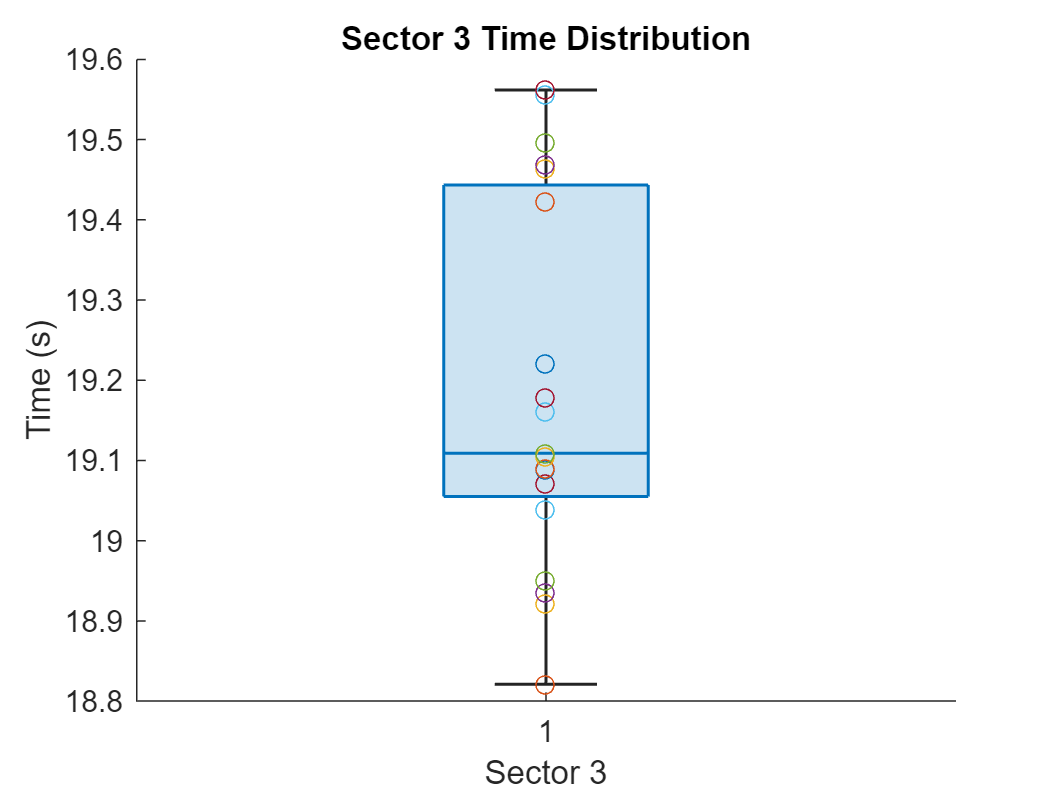


boxchart(sectorTimes(:,3));
hold on
scatter(1, sectorTimes(:,3))
ylabel('Time (s)');
xlabel('Sector 3');
title('Sector 3 Time Distribution');
hold off

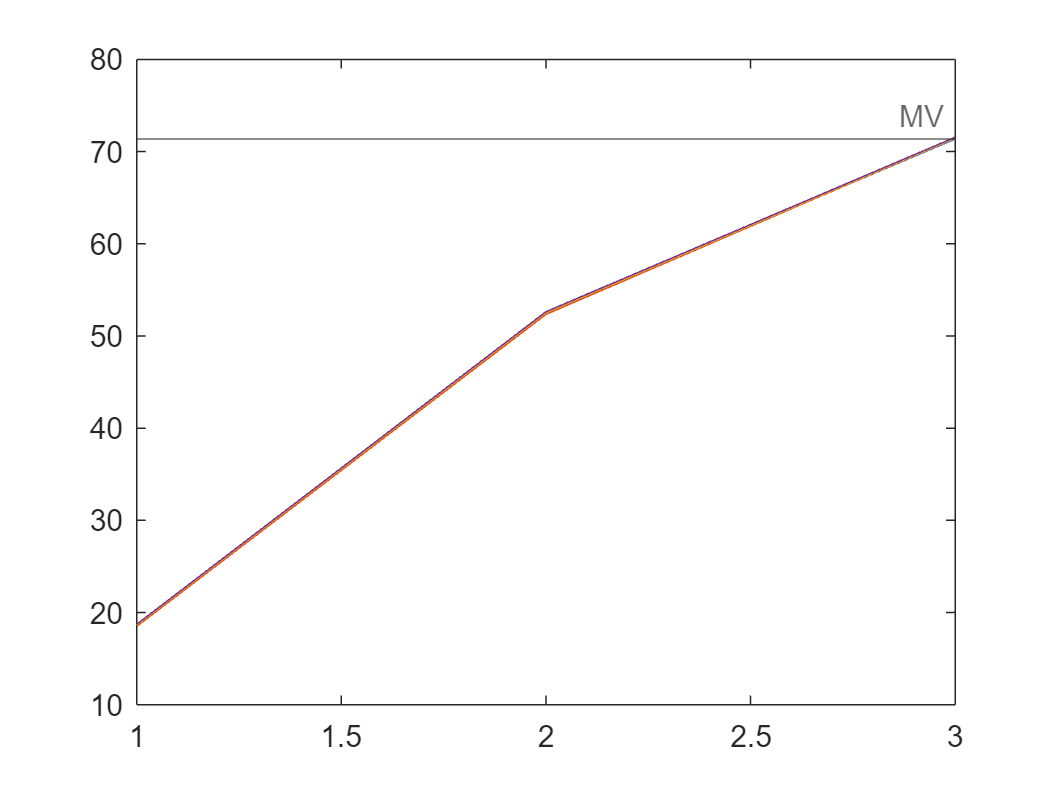

top4Comparison = Monaco_Quali(1:3,1:5);

MV_cumulative = cumsum(top4Comparison.MV);
FA_cumulative = cumsum(top4Comparison.FA);
CL_cumulative = cumsum(top4Comparison.CL);
EO_cumulative = cumsum(top4Comparison.EO);

cumulative_lapTime = [MV_cumulative FA_cumulative CL_cumulative EO_cumulative];

plot([1 2 3], cumulative_lapTime)
hold on
yline(cumulative_lapTime(3,1),"Label","MV")
hold off

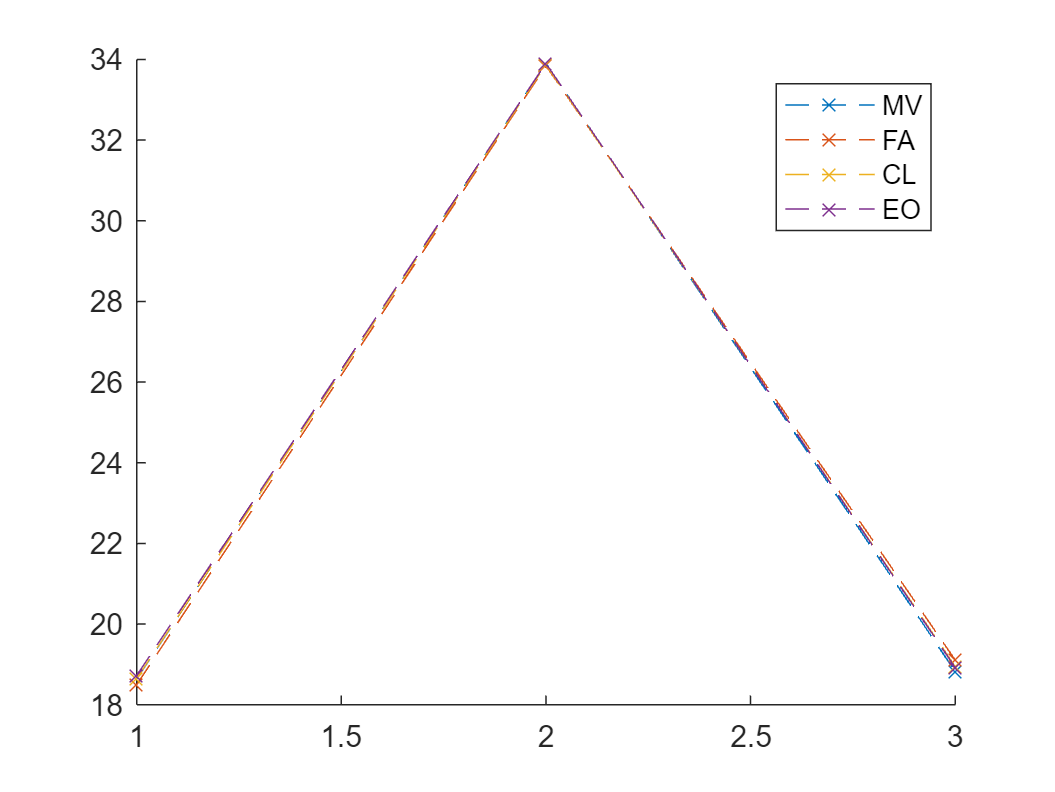


figure
hold on
for i = 2:5
    plot(top4Comparison.(1),top4Comparison.(i),"--x",'DisplayName',top4Comparison.Properties.VariableNames{i});
end
legend
hold off

## Create an array tracking the cumulative delta to Max Verstappen


delta_toMV = zeros(3,4);
for j = 1:4
    delta_toMV(:,j) = cumulative_lapTime(:,j) - cumulative_lapTime(:,1);
end
delta_toMV

delta_toMV =          0   -0.1460    0.0090    0.0860
         0   -0.2040   -0.0230    0.0870
         0    0.0840    0.1060    0.1880


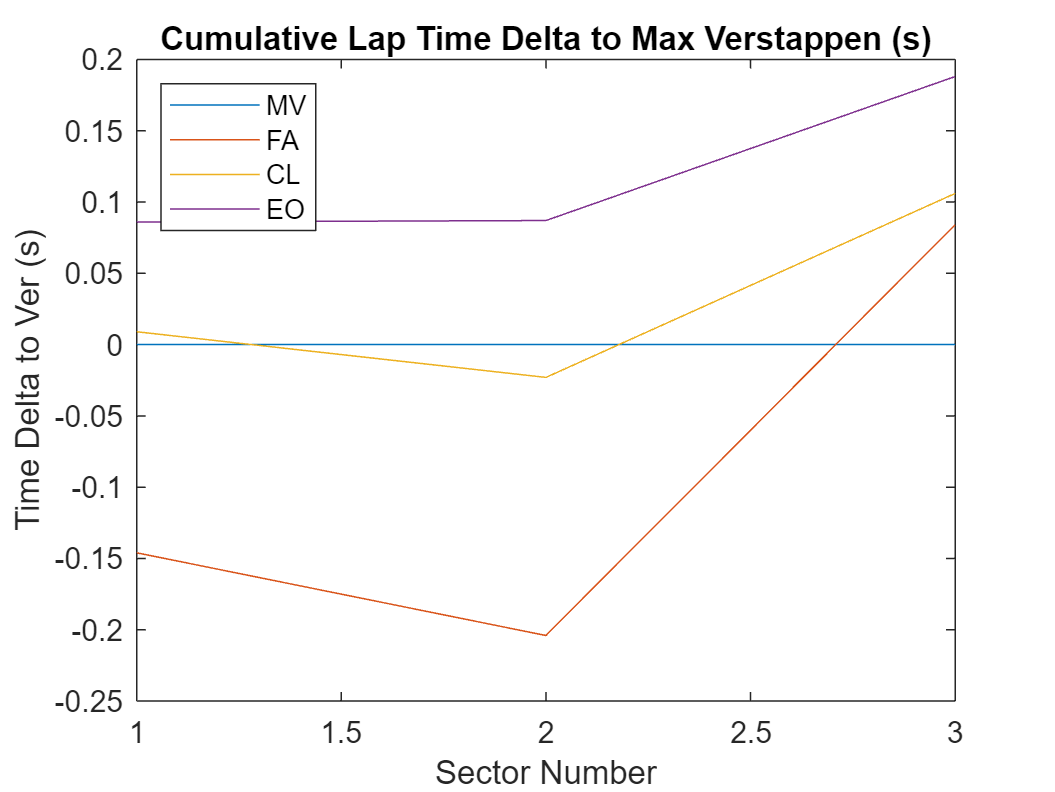


plot(delta_toMV)
title("Cumulative Lap Time Delta to Max Verstappen (s)")
ylabel("Time Delta to Ver (s)")
xlabel("Sector Number")
legend(["MV" "FA" "CL" "EO"],"Location","northwest")